# Travail 1 :

## A1.

On a $T_n \left(f\right)-R_n \left(f\right)=\frac{10}{n}\times \left(f\left(10\right)-f\left(-10\right)\right)$

## A2.

Si $f$s'annule en dehors de $\left\lbrack -8;8\right\rbrack \;$alors $T_n \left(f\right)-R_n \left(f\right)=0$

## B1.

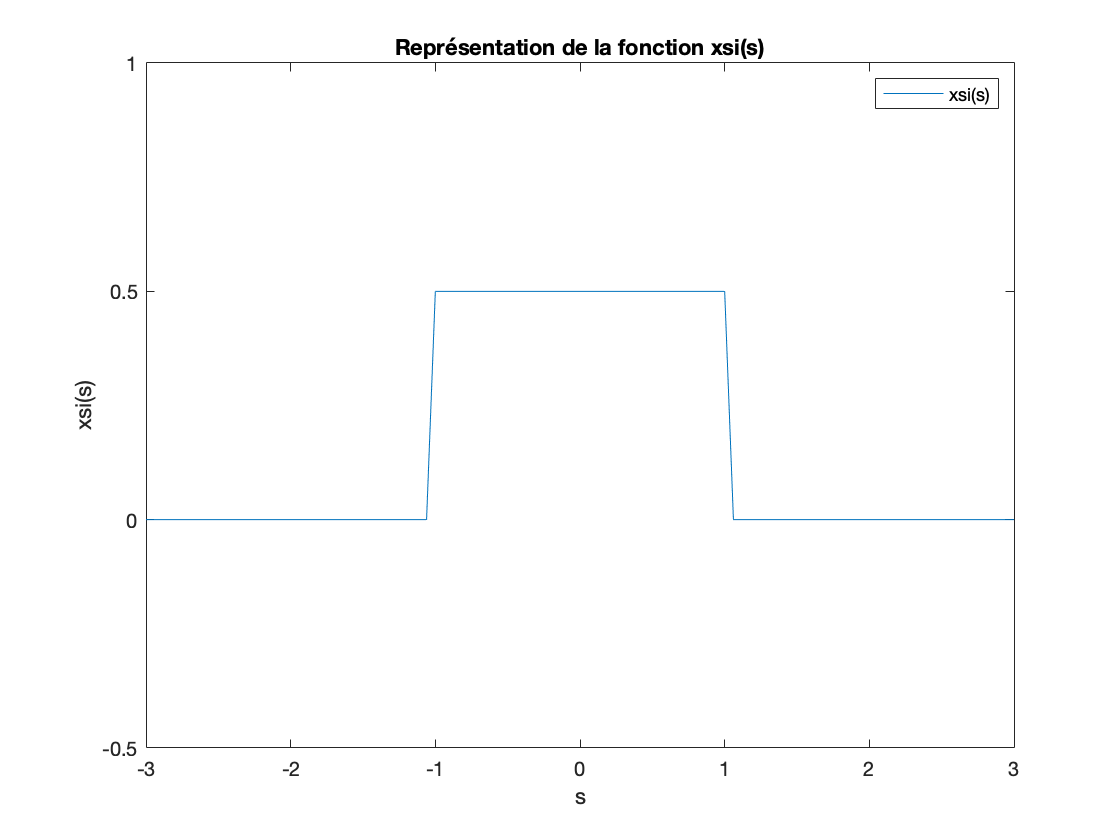

xsi = @(x) (x>=-1).*(x<=1).*0.5;
x = linspace(-3,3,100);
plot(x,xsi(x));
axis([-3 3 -1/2 1])
title("Représentation de la fonction xsi(s)")
legend("xsi(s)")
xlabel("s")
ylabel("xsi(s)")

## B2.

n = [10 50 100];
R = []


R =

     []



T = []


T =

     []



global a
a = -10;
global b 
b = 10;
Rn = @(f,n1) ((b-a)/n1)*sum(f(a+(0:(n1-1))*((b-a)/n1)));
Tn = @(f,n1) ((b-a)/n1)*(((f(a)+f(b))/2) +  sum(f(a+((1:(n1-1))*(b-a)/n1))));
for i=1:(length(n))
    R(i) =Rn(xsi,n(i));
    T(i) =Tn(xsi,n(i));
end
R 

R =     1.0000    1.0000    1.1000


T

T =     1.0000    1.0000    1.1000


## B3.

xsi_conv = @(t,s) xsi((t-s)).*xsi(s);
Rn2 = @(f,t,n1) ((b-a)/n1)* sum(f(t,a+(0:(n1-1))*((b-a)/n1)));
Tn2 = @(f,t,n1) ((b-a)/n1)*(((f(t,a)+f(t,b))/2) +  sum(f(t,a+((1:(n1-1))*(b-a)/n1))));
Ra= []


Ra =

     []



Ta = []


Ta =

     []




for i=1:(length(n))
    T = a+[0:n(i)].*((b-a)/n(i));
    T
    for j=1:length(T)
        Ra(i,j) =Rn2(xsi_conv,T(j),n(i));
        Ta(i,j) =Tn2(xsi_conv,T(j),n(i));
    end
end

T =    -10    -8    -6    -4    -2     0     2     4     6     8    10


T =   -10.0000   -9.6000   -9.2000   -8.8000   -8.4000   -8.0000   -7.6000   -7.2000   -6.8000   -6.4000   -6.0000   -5.6000   -5.2000   -4.8000   -4.4000   -4.0000   -3.6000   -3.2000   -2.8000   -2.4000   -2.0000   -1.6000   -1.2000   -0.8000   -0.4000         0    0.4000    0.8000    1.2000    1.6000    2.0000    2.4000    2.8000    3.2000    3.6000    4.0000    4.4000    4.8000    5.2000    5.6000    6.0000    6.4000    6.8000    7.2000    7.6000    8.0000    8.4000    8.8000    9.2000    9.6000


T =   -10.0000   -9.8000   -9.6000   -9.4000   -9.2000   -9.0000   -8.8000   -8.6000   -8.4000   -8.2000   -8.0000   -7.8000   -7.6000   -7.4000   -7.2000   -7.0000   -6.8000   -6.6000   -6.4000   -6.2000   -6.0000   -5.8000   -5.6000   -5.4000   -5.2000   -5.0000   -4.8000   -4.6000   -4.4000   -4.2000   -4.0000   -3.8000   -3.6000   -3.4000   -3.2000   -3.0000   -2.8000   -2.6000   -2.4000   -2.2000   -2.0000   -1.8000   -1.6000   -1.4000   -1.2000   -1.0000   -0.8000   -0.6000   -0.4000   -0.2000



Ta

Ta =          0         0         0         0         0    0.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.4000    0.3000    0.2000    0.1000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    

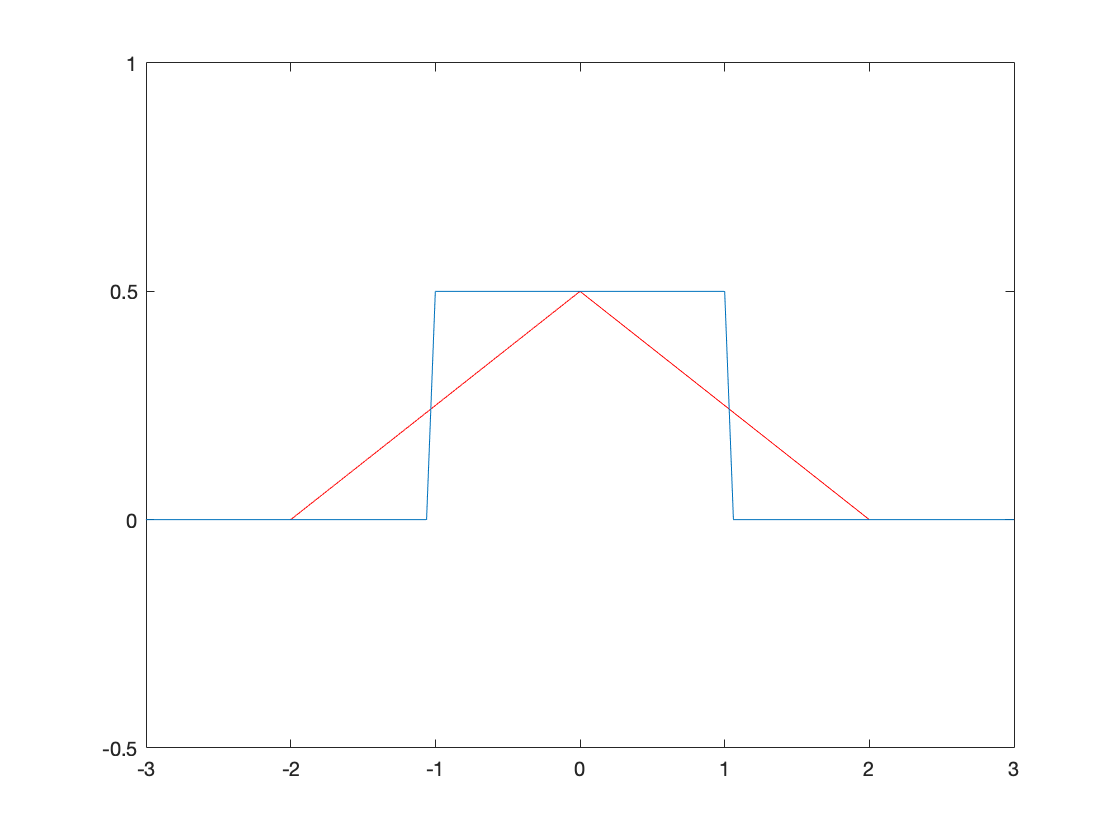

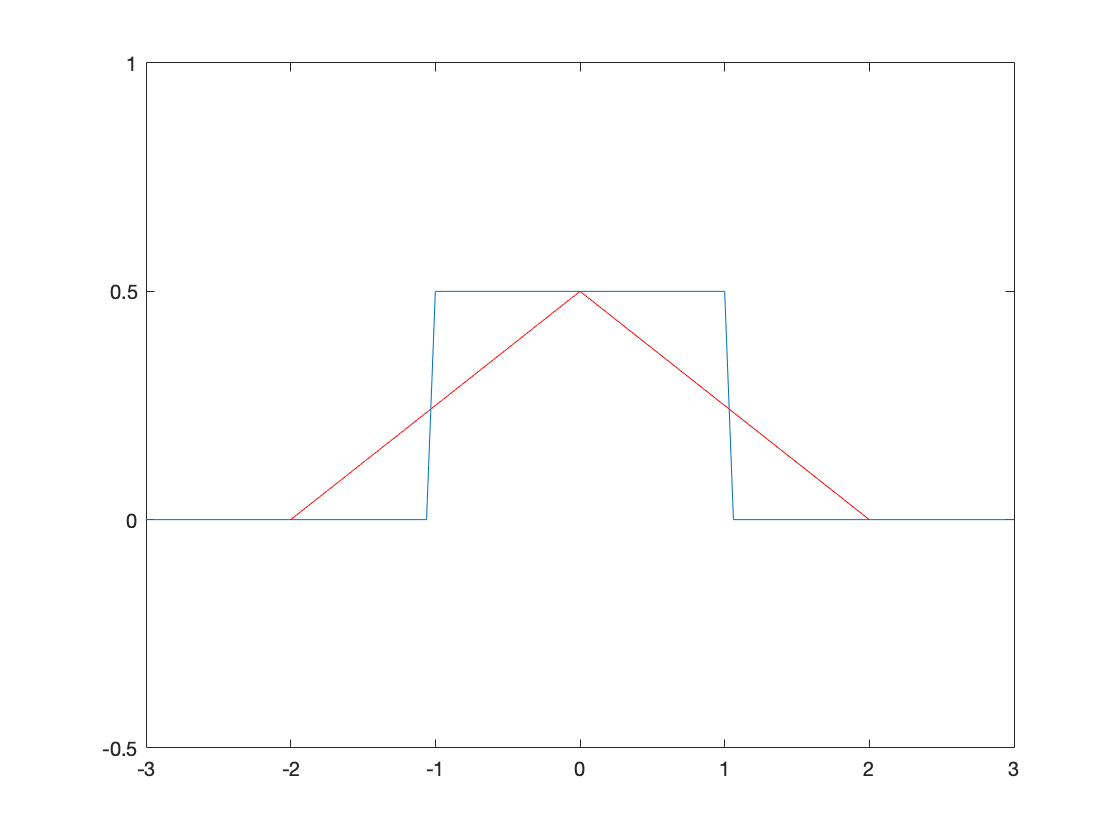

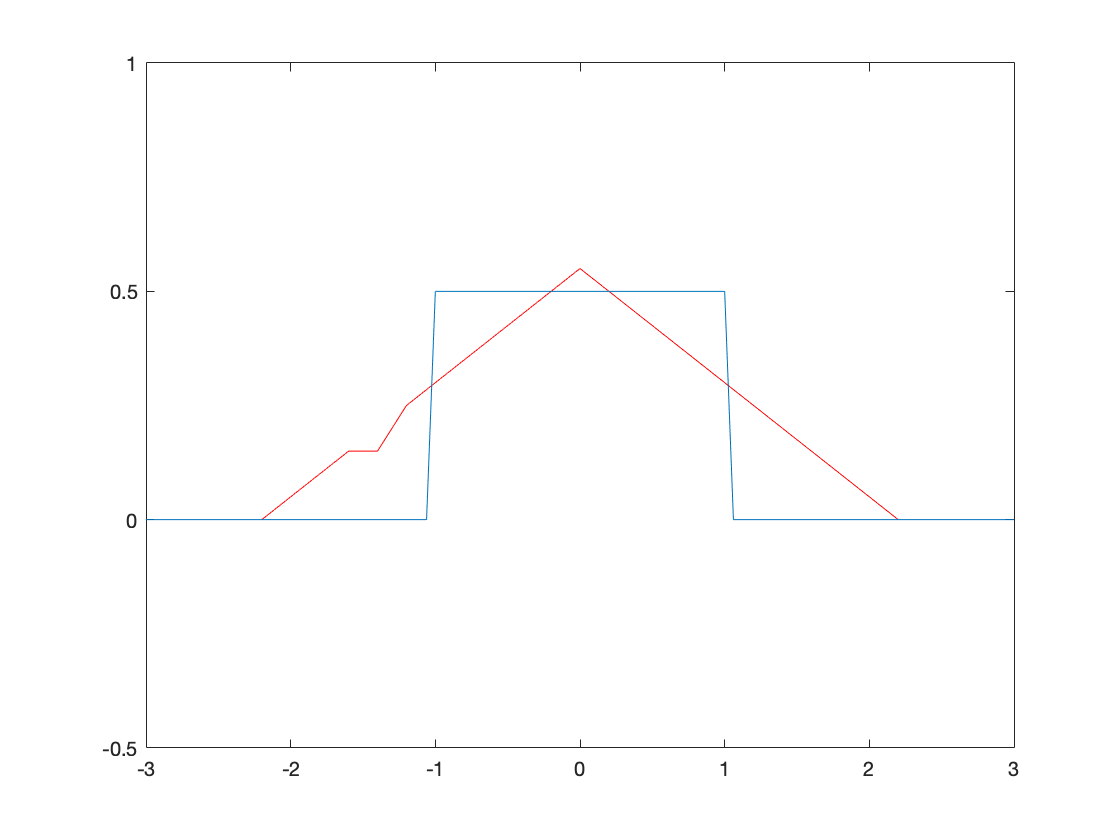

for i=1:3
    figure()
    plot(a+[0:n(i)].*((b-a)/n(i)),Ra(i,1:(n(i)+1)),'Color','red')
    line(x,xsi(x))
    axis([-3 3 -0.5 1])
end

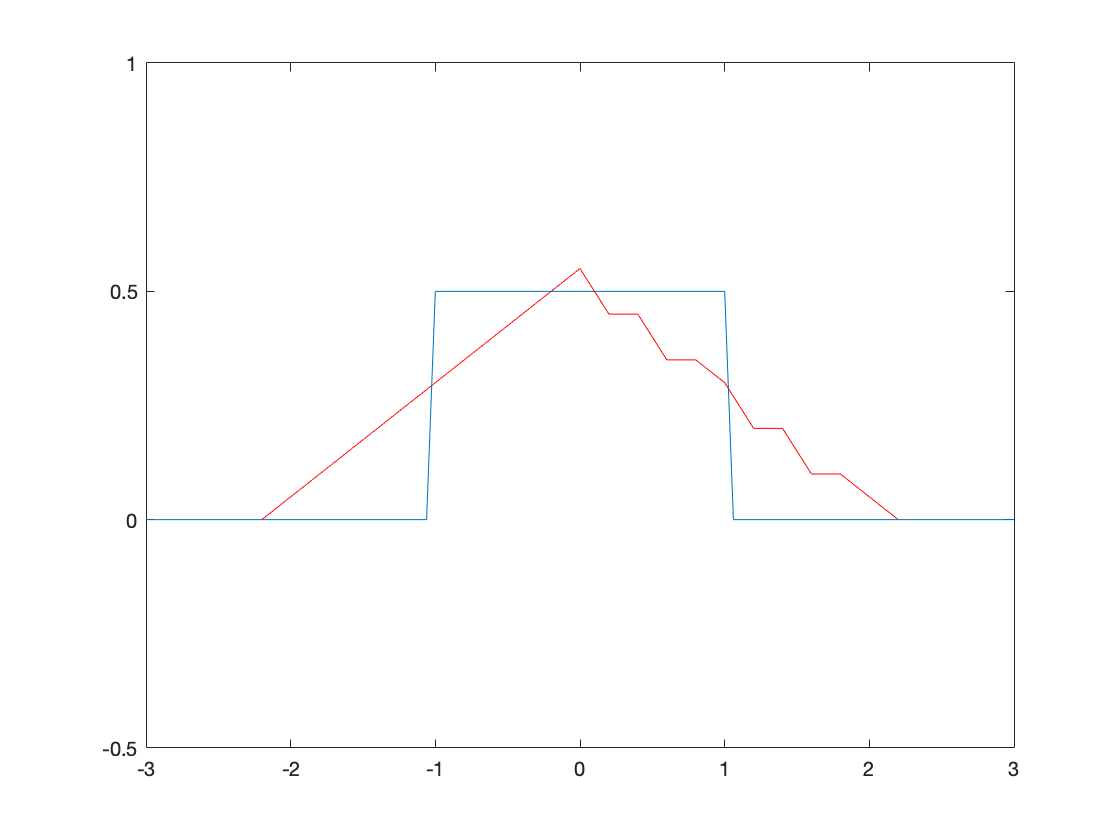

for i=1:3
    figure()
    plot(a+[0:n(i)].*((b-a)/n(i)),Ta(i,1:(n(i)+1)),'Color','red')
    line(x,xsi(x))
    axis([-3 3 -0.5 1])
end